最大裕度的C2设计

clear
denum = [1 3 3 5 4]; 
num = [2 2  3 1];    
Plant = tf(num,denum);
[Q2_num,Q2_denum,alpha_opt]=TwoDOFFeedbackTuningFunction(num,denum);

谱分解无明显误差


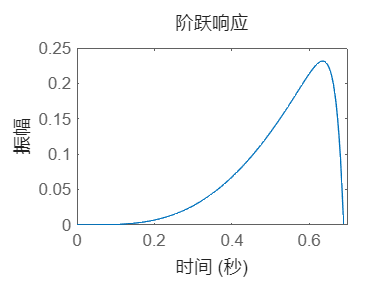

Q2 = tf(Q2_num,Q2_denum);
[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = (Plant*C1)/(1+Plant*C2);
step(T)

普通的C2设计

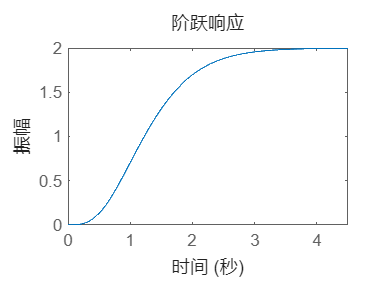

clear
denum = [1 3 3 5 4]; 
num = [2 2 3 1];  
Plant = tf(num,denum);
Q2 = tf([1],[1,100]);
[Q1,C1,C2] = TwoDOFtuningFunction(num,denum,Q2);
T = (Plant*C1)/(1+Plant*C2);
step(T)